% This is the code we used to implement SVD in matlab and try out working with SVD.
% For simplicity's sake, the code we use to plot the SVD of each language and identify the language of texts
% Uses matlab's svd() function.

%Starting with matrix M, letter frequency counts
M = [0, 16, 27, 13, 0, 0, 7, 1, 23, 1, 8, 57, 35, 95, 0, 6, 0, 29, 38, 94, 4, 26, 1, 0, 26, 0; 17, 1, 0, 0, 44, 0, 0, 0, 2, 0, 0, 19, 0, 0, 5, 0, 0, 9, 0, 0, 8, 1, 0, 0, 8, 0; 33, 0, 0, 0, 31, 0, 0, 21, 15, 0, 21, 3, 0, 0, 30, 0, 0, 10, 1, 4, 5, 0, 0, 0, 4, 0; 23, 0, 0, 0, 28, 1, 3, 0, 13, 0, 0, 1, 0, 0, 26, 0, 0, 24, 19, 0, 2, 0, 1, 0, 0, 0; 50, 0, 11, 69, 44, 5, 24, 2, 13, 0, 1, 17, 7, 57, 8, 3, 2, 89, 45, 30, 0, 24, 7, 3, 6, 0; 12, 0, 0, 0, 6, 7, 0, 1, 16, 0, 0, 2, 0, 0, 19, 0, 0, 45, 0, 2, 9, 0, 0, 0, 1, 0; 10, 0, 0, 0, 22, 1, 3, 22, 11, 0, 0, 4, 0, 6, 16, 0, 0, 26, 0, 0, 5, 0, 0, 0, 0, 0; 73, 0, 0, 0, 170, 0, 0, 0, 57, 0, 0, 0, 0, 0, 24, 0, 0, 2, 1, 15, 4, 0, 1, 0, 2, 0; 10, 3, 44, 7, 25, 10, 26, 0, 0, 0, 2, 57, 10, 116, 33, 11, 0, 17, 84, 73, 0, 11, 0, 1, 0, 6; 3, 0, 0, 0, 2, 0, 0, 0, 0, 0, 0, 0, 0, 0, 4, 0, 0, 0, 0, 0, 12, 0, 0, 0, 0, 0; 1, 0, 0, 0, 10, 0, 0, 0, 4, 0, 0, 0, 0, 2, 1, 0, 0, 1, 0, 0, 0, 0, 0, 0, 0, 0; 36, 0, 0, 10, 51, 4, 1, 0, 46, 0, 2, 63, 1, 0, 25, 0, 0, 0, 9, 10, 2, 1, 2, 0, 6, 0; 23, 1, 0, 0, 50, 0, 0, 0, 19, 0, 0, 1, 2, 1, 15, 3, 0, 0, 4, 0, 9, 0, 0, 0, 5, 0; 18, 0, 9, 73, 58, 1, 57, 0, 19, 3, 4, 3, 1, 9, 39, 0, 2, 0, 27, 35, 3, 1, 0, 0, 4, 0; 1, 4, 7, 20, 0, 102, 7, 0, 3, 0, 3, 19, 62, 76, 9, 11, 0, 50, 8, 38, 57, 3, 25, 0, 3, 0; 6, 0, 0, 0, 17, 0, 0, 3, 9, 0, 0, 12, 0, 0, 7, 13, 0, 14, 3, 3, 2, 0, 0, 0, 1, 0; 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 6, 0, 0, 0, 0, 0; 22, 0, 5, 5, 109, 0, 7, 3, 56, 0, 6, 4, 6, 9, 61, 1, 0, 3, 16, 6, 11, 2, 0, 0, 17, 0; 14, 1, 5, 0, 25, 11, 0, 16, 30, 0, 2, 6, 2, 2, 21, 7, 0, 0, 18, 63, 8, 0, 4, 0, 3, 0; 23, 0, 0, 0, 56, 1, 0, 216, 86, 0, 0, 3, 0, 0, 90, 0, 0, 20, 11, 7, 7, 0, 0, 0, 23, 0; 7, 1, 1, 2, 6, 4, 5, 0, 7, 0, 0, 14, 3, 27, 0, 7, 0, 27, 36, 19, 0, 0, 0, 1, 0, 0; 7, 0, 0, 0, 58, 0, 0, 0, 11, 0, 0, 0, 0, 0, 4, 0, 0, 0, 0, 0, 0, 0, 0, 0, 1, 0; 10, 0, 1, 0, 40, 0, 0, 29, 47, 0, 0, 0, 0, 6, 7, 0, 0, 2, 1, 0, 0, 0, 0, 0, 0, 0; 1, 0, 0, 0, 0, 0, 0, 0, 1, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 2, 1, 0, 0, 0, 0, 0; 0, 2, 0, 0, 6, 0, 0, 0, 2, 0, 0, 1, 2, 0, 12, 0, 0, 0, 6, 2, 0, 0, 0, 0, 0, 0; 0, 0, 0, 0, 5, 0, 0, 0, 1, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0];

%Finding the matrix multiplication of M and Mtranspose and vice versa
MMt = M*(M.');
MtM = (M.')*M;

%Finding the eigenvectors of MMt, stuffing into matrix, D contains eigenvalues
[eigvectorsMMt, D] = eig(MMt);
%Finding the eigenvectors of MtM, stuffing into matrix
[eigvectorsMtM, E] = eig(MtM);

%Creating zero vectors V and U to stuff normalized versions of eigenvector matrices
V = zeros(26, 26)

V =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0

U = zeros(26, 26)

U =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0

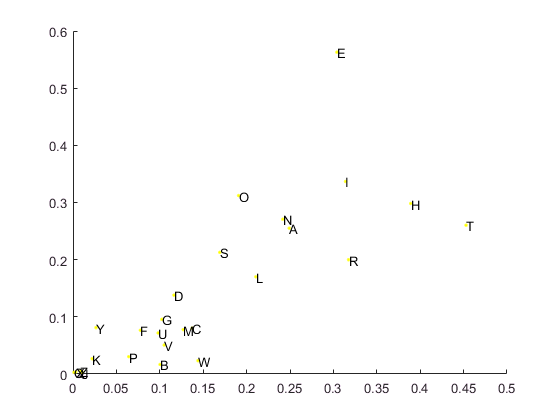


%Forming normalized V and U
for n = 1:26
    m = 27-n;
    v = eigvectorsMMt(:, n);     %v is the nth column(:) of matrix with eigenvector of MMt
    V(:, m) = eigvectorsMMt(:, n)/norm(v);     %Creating nth column of V
    u = eigvectorsMtM(:, n);
    U(:, m) = eigvectorsMtM(:, n)/norm(u);
end

figure
hold on
x = V(:, 1);
y = U(:, 1);
    
plot(x, y, 'y.')
labels = {'A', 'B', 'C', 'D', 'E', 'F', 'G', 'H', 'I', 'J', 'K', 'L', 'M', 'N', 'O', 'P', 'Q', 'R', 'S', 'T', 'U', 'V', 'W', 'X', 'Y', 'Z'};
text(x, y, labels)
hold off

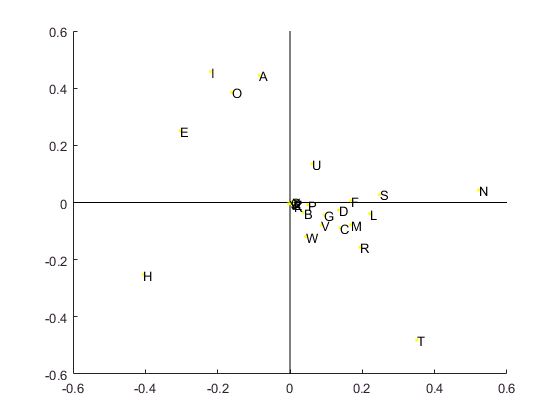


figure
hold on
plot([-.6 .6], [0 0], 'k')
plot([0 0], [-.6 .6], 'k')
x = U(:, 2);
y = V(:, 2);
    
plot(x, y, 'y.')
text(x, y, labels)
hold off


%Creating Vtranspose
Vt = V.';   

%Creating matrix of singular Values S
S = sqrt(D);


%Created to test recreation of MMt, worked as expected
X = zeros(26, 26)

X =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0

for n = 1:26
    v = V(:, n);
    vt = v.';
    x = v*vt*D(n,n);
    X = X + x;
end
%X

U(8, 2)

ans = -0.4052


V(8, 2)

ans = -0.2523


M2 = U*S*Vt;

[a,b,c] = svd(M);

M3 = b * a * c;

